# 1. Selecionar dados

clear; clc; close all;
[nome,pasta]=uigetfile('*.csv','Selecionar ensaio_viga_mock.csv');
if isequal(nome,0), disp('Selecao cancelada.'); return; end
T=readtable(fullfile(pasta,nome));
t=T.Tempo_s; F=T.Forca_N; e=T.Deformacao_ue;
assert(all(diff(t)>0),'O tempo deve ser estritamente crescente.');
dt=median(diff(t)); fs=1/dt;
assert(max(abs(diff(t)-dt))<1e-6,'Amostragem irregular: rever tratamento.');
fprintf('N=%d; fs=%.1f Hz; duracao=%.1f s\n',height(T),fs,t(end)-t(1));

N=7001; fs=50.0 Hz; duracao=140.0 s


fprintf('Dados ausentes: forca=%d; deformacao=%d\n',sum(ismissing(F)),sum(ismissing(e)));

Dados ausentes: forca=0; deformacao=3


## 2. Inspecionar os dois canais antes de corrigir

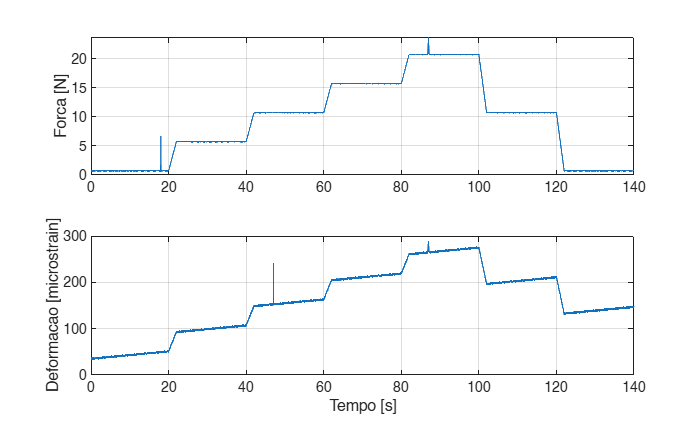

figure('Name','Dados brutos');
subplot(2,1,1); plot(t,F); grid on; ylabel('Forca [N]');
subplot(2,1,2); plot(t,e); grid on; ylabel('Deformacao [microstrain]'); xlabel('Tempo [s]');

% Fazer zoom perto de 18, 47, 65 e 87 s. Os canais corroboram o evento?

## 3. Corrigir o zero com um intervalo conhecido SEM CARGA

Nao subtrair a media de TODO o ensaio: apagaria parte da carga real.

base=t>=2 & t<=10;
Fzero=mean(F(base),'omitnan'); ezero=mean(e(base),'omitnan');
Fc=F-Fzero; ec=e-ezero;
fprintf('Offsets estimados: %.4f N e %.4f microstrain\n',Fzero,ezero);

Offsets estimados: 0.7001 N e 39.7990 microstrain


% A correcao do zero nao elimina a deriva ao longo do tempo.

## 4. Falhas de leitura: preencher apenas uma lacuna muito curta

Guardar mascara e canais originais. A interpolacao nao e uma medicao.

ausente=ismissing(ec);
ei=fillmissing(ec,'linear','SamplePoints',t,'MaxGap',0.10);
assert(~any(ismissing(ei)),'Ficaram lacunas: requerem avaliacao individual.');

## 5. Procurar candidatos a artefactos (nao apagar automaticamente)

Mediana local robusta: desvio elevado apenas sinaliza uma suspeita.

medF=movmedian(Fc,11,'omitnan'); mede=movmedian(ei,11,'omitnan');
suspeitaF=abs(Fc-medF)>0.5;
suspeitaE=abs(ei-mede)>12;
fprintf('Candidatos: forca=%d; deformacao=%d\n',sum(suspeitaF),sum(suspeitaE));

Candidatos: forca=4; deformacao=1


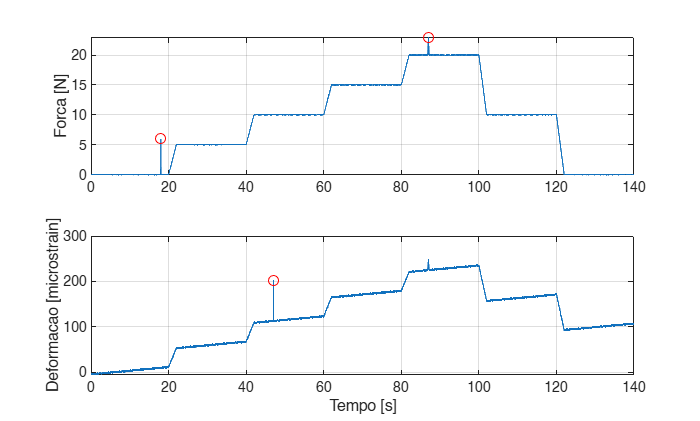

figure('Name','Candidatos nao sao erros confirmados');
subplot(2,1,1); plot(t,Fc); hold on; plot(t(suspeitaF),Fc(suspeitaF),'ro'); grid on;
ylabel('Forca [N]');
subplot(2,1,2); plot(t,ei); hold on; plot(t(suspeitaE),ei(suspeitaE),'ro'); grid on;
ylabel('Deformacao [microstrain]'); xlabel('Tempo [s]');

% O evento a 87 s e coerente nos dois canais. Investigar antes de remover!
% Neste ensaio, o registo de ocorrencias confirma artefactos isolados a 18 e 47 s.
erroF=abs(t-18)<dt/4; erroE=abs(t-47)<dt/4;
Flim=Fc; elim=ei;
Flim(erroF)=NaN; elim(erroE)=NaN;
Flim=fillmissing(Flim,'linear','SamplePoints',t,'MaxGap',0.10);
elim=fillmissing(elim,'linear','SamplePoints',t,'MaxGap',0.10);

## 6. Suavizacao: comparar janelas e observar o que se perde

Janela impar centrada; analise offline. Nao e filtro anti-aliasing.

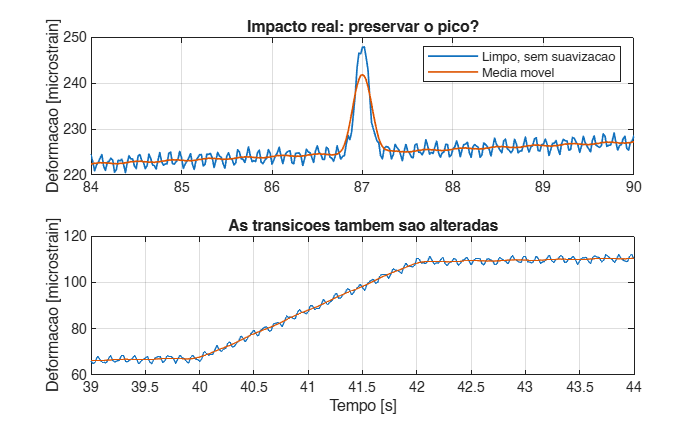

janela_s=0.20; % experimentar 0.04, 0.20 e 1.00
njan=2*floor(janela_s*fs/2)+1;
esuave=movmean(elim,njan);
Fsuave=movmean(Flim,njan);
figure('Name','Efeito da suavizacao');
subplot(2,1,1); plot(t,elim,t,esuave,'LineWidth',1); grid on;
xlim([84 90]); ylabel('Deformacao [microstrain]');
legend('Limpo, sem suavizacao','Media movel'); title('Impacto real: preservar o pico?');
subplot(2,1,2); plot(t,elim,t,esuave); grid on;
xlim([39 44]); ylabel('Deformacao [microstrain]'); xlabel('Tempo [s]');
title('As transicoes tambem sao alteradas');

% Nunca substituir o unico registo original pelos dados suavizados.

## 7. Estatistica em patamares estaveis, antes da suavizacao

Janelas escolhidas apos inspecao: evitar rampas e o impacto real.

inicios=(0:20:120)'+10; finais=(0:20:120)'+17;
alvos=[0;5;10;15;20;10;0];
Fmedia=zeros(7,1); Fdp=Fmedia; Emedia=Fmedia; Edp=Fmedia; N=Fmedia;
for k=1:7
    ix=t>=inicios(k) & t<=finais(k);
    N(k)=sum(ix); Fmedia(k)=mean(Flim(ix)); Fdp(k)=std(Flim(ix));
    Emedia(k)=mean(elim(ix)); Edp(k)=std(elim(ix));
end
resumo=table(alvos,inicios,finais,N,Fmedia,Fdp,Emedia,Edp, ...
 'VariableNames',{'Carga_nominal_N','Inicio_s','Fim_s','N','Forca_media_N', ...
 'Forca_DP_N','Deformacao_media_ue','Deformacao_DP_ue'});
disp(resumo);

    Carga_nominal_N    Inicio_s    Fim_s     N     Forca_media_N    Forca_DP_N    Deformacao_media_ue    Deformacao_DP_ue
    _______________    ________    _____    ___    _____________    __________    ___________________    ________________

           0              10         17     351     -1.3769e-05      0.028972            6.002                1.9759     
           5              30         37     351          4.9999      0.028843           62.013                1.9757     
          10              50         57     351          9.9999      0.028908              118                 1.981     
          15              70         77     351              15      0.028868              174                1.9731 

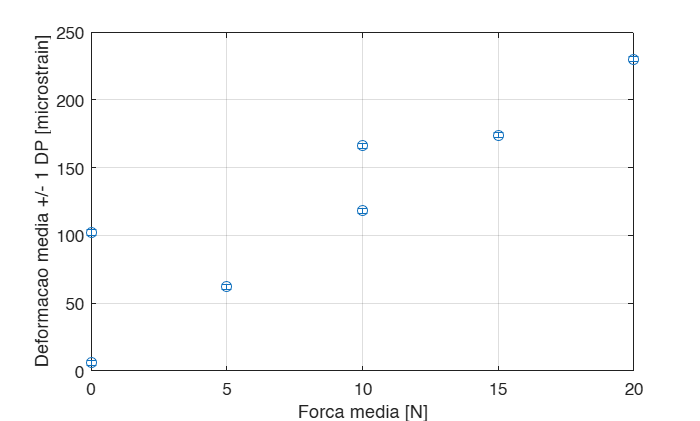

figure('Name','Patamares');
errorbar(Fmedia,Emedia,Edp,'o','LineStyle','none'); grid on;
xlabel('Forca media [N]'); ylabel('Deformacao media +/- 1 DP [microstrain]');

% DP descreve dispersao temporal. Nao e incerteza total nem IC da media.

## 8. Avaliar retorno ao zero e preservar rastreabilidade

fprintf('Retorno ao zero: F=%.4f N; e=%.4f microstrain\n',Fmedia(end),Emedia(end));

Retorno ao zero: F=-0.0001 N; e=102.0128 microstrain


% Um offset constante nao corrige a deriva. Nao fazer detrend cegamente:
% pode remover resposta mecanica real. Sugerir referencia independente.
tratados=table(t,F,e,Fc,ec,Flim,elim,Fsuave,esuave, ...
 ausente,erroF,erroE,'VariableNames',{'Tempo_s','Forca_bruta_N', ...
 'Deformacao_bruta_ue','Forca_zero_N','Deformacao_zero_ue', ...
 'Forca_limpa_N','Deformacao_limpa_ue','Forca_suave_N','Deformacao_suave_ue', ...
 'Deformacao_interpolada','Artefacto_forca_corrigido','Artefacto_deformacao_corrigido'});
% Guardar na pasta dos dados selecionados, sem depender da pasta temporaria.
writetable(resumo,fullfile(pasta,'resumo_patamares.csv'));
writetable(tratados,fullfile(pasta,'dados_tratados.csv'));
save(fullfile(pasta,'resultados_exemplo2.mat'),'T','tratados','resumo', ...
 'Fzero','ezero','fs','njan','inicios','finais');

## 9. Perguntas para responder

1. Porque nao remover a media global? 2. O que distingue 47 s de 87 s? 3. Quanto muda o pico a 87 s com a janela de 1 s? 4. Porque calcular DP antes da suavizacao? 5. O patamar final regressa a zero? Propor causas e verificacoes. 6. Alterar as janelas para incluir as rampas: como muda o DP?

## 10. Comparação final: antes e depois do tratamento

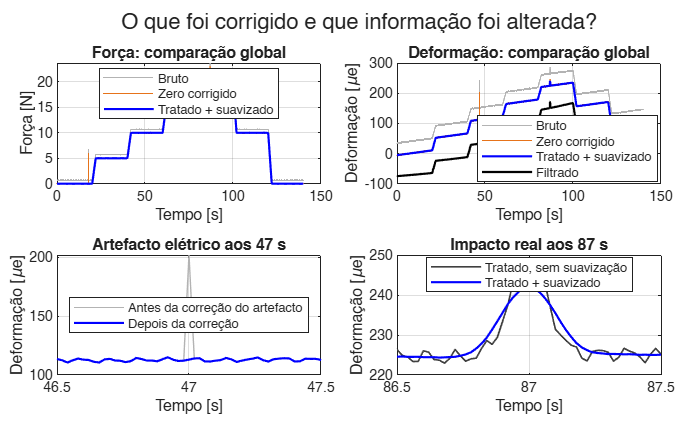

% Comparar os sinais e observar o efeito das diferentes operações.
%
% F, e           -> dados originais
% Fc, ec         -> dados apenas com correção do zero
% Flim, elim     -> dados com zero corrigido e artefactos tratados
% Fsuave, esuave -> dados anteriores com média móvel aplicada

figure('Name', 'Comparação final: antes e depois', ...
    'Color', 'w');

tiledlayout(2, 2, 'TileSpacing', 'compact', ...
    'Padding', 'compact');

%% Força: comparação global
nexttile;

plot(t, F, 'Color', [0.70 0.70 0.70]);
hold on;
plot(t, Fc, 'Color', [0.90 0.45 0.10]);
plot(t, Fsuave, 'b', 'LineWidth', 1.3);

grid on;
xlabel('Tempo [s]');
ylabel('Força [N]');
title('Força: comparação global');

legend('Bruto', 'Zero corrigido', 'Tratado + suavizado', ...
    'Location', 'best');

%% Deformação: comparação global
nexttile;

plot(t, e, 'Color', [0.70 0.70 0.70]);
hold on;
plot(t, ec, 'Color', [0.90 0.45 0.10]);
plot(t, esuave, 'b', 'LineWidth', 1.3);
efiltrado= lowpass(elim, 5, fs);
efiltrado= highpass(efiltrado, 0.001, fs);
plot(t, efiltrado, 'black', 'LineWidth', 1.3);

grid on;
xlabel('Tempo [s]');
ylabel('Deformação [\mue]');
title('Deformação: comparação global');

legend('Bruto', 'Zero corrigido', 'Tratado + suavizado','Filtrado', ...
    'Location', 'best');

%% Artefacto elétrico: efeito da correção
% Comparar depois de corrigir o zero em ambos os sinais,
% para que o offset não esconda o efeito do tratamento.
nexttile;

plot(t, ec, 'Color', [0.70 0.70 0.70]);
hold on;
plot(t, elim, 'b', 'LineWidth', 1.3);

xlim([46.5 47.5]);
grid on;
xlabel('Tempo [s]');
ylabel('Deformação [\mue]');
title('Artefacto elétrico aos 47 s');

legend('Antes da correção do artefacto', ...
    'Depois da correção', 'Location', 'best');

%% Impacto físico: efeito da suavização
% O impacto é real e deve permanecer nos dados limpos.
nexttile;

plot(t, elim, 'Color', [0.25 0.25 0.25], ...
    'LineWidth', 1);
hold on;
plot(t, esuave, 'b', 'LineWidth', 1.3);

xlim([86.5 87.5]);
grid on;
xlabel('Tempo [s]');
ylabel('Deformação [\mue]');
title('Impacto real aos 87 s');

legend('Tratado, sem suavização', ...
    'Tratado + suavizado', 'Location', 'best');

sgtitle('O que foi corrigido e que informação foi alterada?');